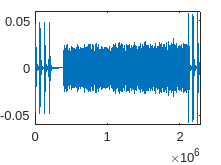

K = 2048;           % total number of subcarriers
L = 200;            % number of zero-padded symbols
numOfTaps = L + 1;  % number of channel taps
Fc = 24000;         % Carrier Frequency
B = 8000;           % Bandwidth. [ 0 to 8000] in baseband
W = 24;             % number of ZP-OFDM symbols in one packet
Lambda = 24;        % Oversampling Factor
Sampler = 256000;
vel = 1.03;
c = 1500;
%a = vel/c;

%%% Step 1: PB filter to remove noise beyond PB
load("data_project_2/benchmark_rece_data_174623_1472.mat") %brings in rece_data_ofdm_bench
load("data_project_2/test_rece_data_173048_1472.mat"); %brings in rece_data_ofdm_test
y_in = rece_data_ofdm_bench; %rece_data_ofdm_test
%plot(y_in);
%ypb = zeros(length(y_in), 1);
ypb = bandpass(y_in, [-1000+Fc, 8000+Fc], Sampler);
plot(ypb);


%%% Step 2: Estimate a
Ttx = 8269.52; %In ms
Ttxs = Ttx / 1000; %In sec
sr = 1 / Sampler; %Sampling rate in seconds
Trxest = 2117460 * sr; %Estimated Trx duration in sec
a = Ttxs/Trxest

a = 0.9998

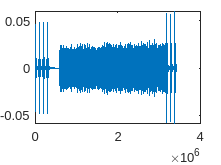


%%% Step 3: Resampling
ypb_re = resample(ypb, round((1+a)*1*exp(5)), round(1*exp(5))); %%% Double check with TA

%%% Step 4: Resampling from 256k to 192k
Ls = 192;
Ms = 256;
Lp = 24;
N = Lp*Ls-1;
h = Ls*fir1(N, 1/Ms, kaiser(N+1, 7.8562));
Ytildapb_re = upfirdn(ypb_re, h, Ls, Ms);
plot(Ytildapb_re);

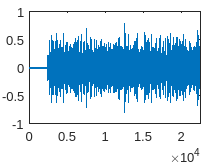

%freqz(Ytildapb_re, 1);

%%% Step 5: Synchronization
load("data_project_2/pilot_signal_for_synchronization.mat") % brings in OFDM_Data_pre_old
pilotpb = OFDM_data_pre_old;
plot(pilotpb)